clearvars;
% create the computational grid
xSize = 0.7;        % height of grid in meters
ySize = 0.3;        % length of grid in meters
Nx = 128;           % number of grid points in the x (row) direction
Ny = 64;            % number of grid points in the y (column) direction
dx = xSize/Nx;    	% grid point spacing in the x direction [m]
dy = ySize/Ny;      % grid point spacing in the y direction [m]
kgrid = kWaveGrid(Nx, dx, Ny, dy);
% define sound speed in the two layers
c1 = 1500;          % water
%c2 = 1600;         % sediment
c2 = 5100;          % aluminium
%c2 = 3700;          %concrete
% define the properties of the propagation medium
medium.sound_speed = c1 * ones(Nx, Ny);     % [m/s]
medium.sound_speed(round(Nx/3):round(Nx/3)+5, Ny/2-3:Ny/2+3) = c2;
%medium.sound_speed(Nx/2:Nx/2+5, Ny/2-3:Ny/2+3) = c2;
medium.density = 1000 * ones(Nx, Ny);       % [kg/m^3]
%medium.density(Nx/2:Nx/2+5, Ny/2-3:Ny/2+3) = 2700; %aluminium
medium.density(round(Nx/3):round(Nx/3)+5, Ny/2-3:Ny/2+3) = 2700;
%medium.density(Nx/2:Nx/2+5, Ny/2-3:Ny/2+3) = 2300; %concrete
%medium.density(Nx/2:Nx/2+5, Ny/2-3:Ny/2+3) = 1500;  % sediment
medium.alpha_coeff = 0.75;                  % [dB/(MHz^y cm)]
medium.alpha_power = 1.5;

% create the time array
kgrid.makeTime(medium.sound_speed);
% I had to increase the number of time steps Nt because the simulation was
% ending too early to view the whole backscatter plot. I used the
% kgrid.makeTime() method to see what the algorithm had used, then manually
% set kgrid.dt to be the same and kgrid.Nt to be slightly larger until the
% simulation ran for an appropriate amount of time - for sediment, not Al
kgrid.Nt

ans = 1842

kgrid.dt

ans = 2.7574e-07

kgrid.Nt = 2000;
%kgrid.dt = 2.7574e-7;
% define a source mask for a linear element transducer with an odd number
% of elements

num_elements = 21;
source.p_mask = zeros(Nx, Ny);
x_offset = 5;
y_offset = 20;
start_index = Ny/2 - round(num_elements/2) + 1;
source.p_mask(x_offset, start_index:start_index + num_elements - 1) = 1;

% define the properties of the tone burst
sampling_freq = 1/kgrid.dt;     % [Hz]
%sampling_freq = 20e6;
steering_angle = 0;            % [deg]
element_spacing = dx;           % [m]
tone_burst_freq = 200e3;  %(Hz) frequency of source pulse
tone_burst_cycles = 2;

% create an element index relative to the centre element of the transducer
element_index = -(num_elements - 1)/2:(num_elements - 1)/2;

% use geometric beam forming to calculate the tone burst offsets for each
% transducer element based on the element index
tone_burst_offset = 200 + element_spacing * element_index * ...
    sin(steering_angle * pi/180) / (c1 * kgrid.dt);

% create the tone burst signals
signal = toneBurst(sampling_freq, tone_burst_freq, tone_burst_cycles, ...
    'SignalOffset', tone_burst_offset, 'Envelope', 'Gaussian');
signal = gaussianFilter(signal, sampling_freq, tone_burst_freq, 1000);
source.p = signal;
%source.p = toneBurst(sampling_freq, tone_burst_freq, tone_burst_cycles, ...
%    'SignalOffset', tone_burst_offset, 'Envelope', 'Gaussian');
%source.p = smooth(source.p, true)
% assign the input options
input_args = {'DisplayMask', source.p_mask, 'PMLInside', false, 'PlotLayout', true};

%define sensor mask
sensor.mask = zeros(Nx, Ny);
sensor.mask(x_offset, start_index:start_index + num_elements - 1) = 1;
% sensor.mask(x_offset+1, 32) = 1;

Running k-Wave simulation...
  start time: 23-May-2023 08:39:03
  reference sound speed: 5100m/s
  dt: 275.7353ns, t_end: 551.1949us, time steps: 2000
  input grid size: 128 by 64 grid points (700 by 300mm)
  maximum supported frequency: 137.1429kHz by 160kHz
  expanding computational grid...
  computational grid size: 168 by 104 grid points
           Use dimension sizes with lower prime factors to improve speed


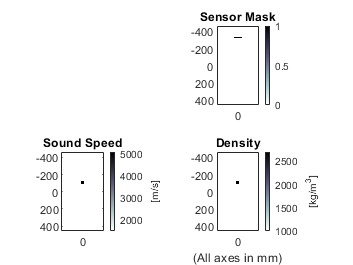

  precomputation completed in 0.63096s
  starting time loop...
  estimated simulation time 12.52s...


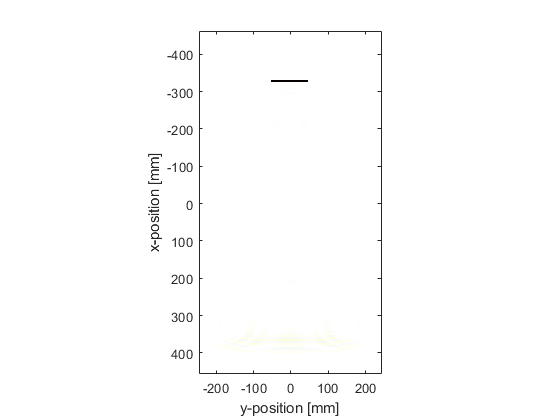

  simulation completed in 10.9918s
  total computation time 11.659s




% run the simulation
    sensor_data = kspaceFirstOrder2D(kgrid, medium, source, sensor, input_args{:});

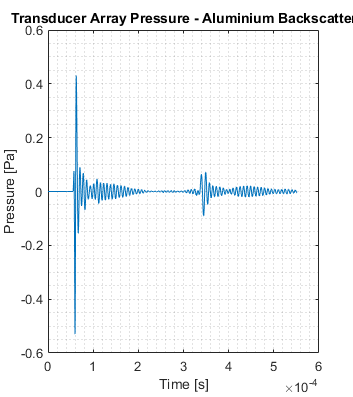


%plot pressure data at middle element
mid_element = round(num_elements/2);
figure;
plot(kgrid.t_array,sensor_data(6, :));
xlabel('Time [s]');
ylabel('Pressure [Pa]');
title("Transducer Array Pressure - Aluminium Backscatter")
scaleFig(1, 1.5);
grid minor;

% data analysis
sep = 1000;
alltimesensor = sensor_data(mid_element,:)

alltimesensor =     0.0000    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000


initialWave = sensor_data(mid_element,220:750)

initialWave =    -0.4204   -0.2908   -0.1331    0.0301    0.1782    0.2960    0.3758    0.4175    0.4262    0.4097    0.3764    0.3329    0.2844    0.2337    0.1826    0.1321    0.0830    0.0362   -0.0076   -0.0472   -0.0814   -0.1091   -0.1298   -0.1431   -0.1489   -0.1475   -0.1394   -0.1254   -0.1064   -0.0835   -0.0581   -0.0313   -0.0044    0.0212    0.0444    0.0643    0.0800    0.0909    0.0967    0.0974    0.0931    0.0841    0.0712    0.0551    0.0367    0.0172   -0.0026   -0.0215   -0.0386   -0.0531


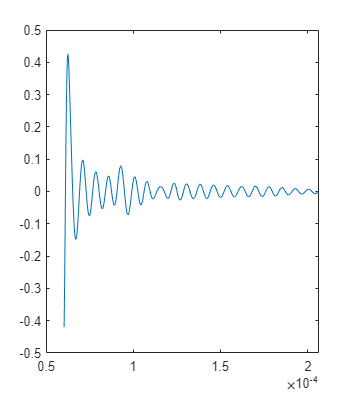

plot(kgrid.t_array(220:750),initialWave);

reflectedWave = sensor_data(mid_element,1220:1750)

reflectedWave =     0.0074    0.0151    0.0235    0.0322    0.0410    0.0494    0.0570    0.0636    0.0685    0.0717    0.0727    0.0713    0.0675    0.0612    0.0526    0.0416    0.0288    0.0144   -0.0012   -0.0173   -0.0335   -0.0491   -0.0637   -0.0766   -0.0873   -0.0954   -0.1006   -0.1026   -0.1013   -0.0968   -0.0892   -0.0787   -0.0658   -0.0508   -0.0345   -0.0172    0.0002    0.0172    0.0332    0.0475    0.0597    0.0694    0.0762    0.0800    0.0807    0.0783    0.0731    0.0654    0.0554    0.0438


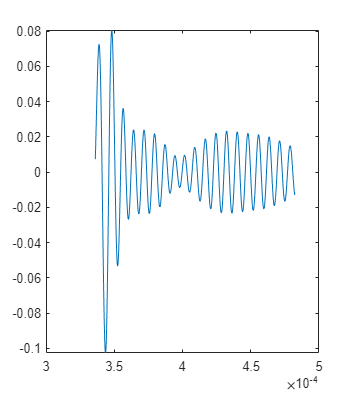

plot(kgrid.t_array(1220:1750),reflectedWave);


[refcf, refmag] = A_getReflectCoeff(initialWave,reflectedWave,0)

refcf = 0.1892

refmag = 0.0807


wavL = A_getWavelength(reflectedWave,kgrid.t_array(1220:1750)) % this is actually time period...

wavL = 7.7600e-06


freq = A_getFrequency(initialWave,kgrid.t_array(220:750))

freq = 1.3082e+05


1/wavL

ans = 1.2887e+05